# Laboratório de Instrumentação Industrial

## *Relatório 01*

## *Caracterização Estática de Instrumentos - Calibração*

#### *Aulas Práticas 3, 4, 5 e 6*

#### Nome(s) Completo(s): 

Prezados(as) estudantes,

O MATLAB LIVE EDITOR é uma ferramenta interativa do MATLAB que combina código, saídas de execução, figuras e texto em um único documento.

Para elaborar este relatório, siga atentamente as orientações abaixo, implementando os trechos de código para calcular o que se pede.

O relatório será avaliado em cima do que for compreendido pelo professor, portanto, garanta que as funções e comandos utilizados estejam claros e muito bem comentados (%). Para isso:

- Dê **nomes intuitivos** para suas variáveis, bem como coloque um comentário descritivo sobre cada uma;

- **Comente o seu código** sempre que necessário, visto que ele será corrigido como uma memória de cálculo;

- Dê **título** para os gráficos, **nome** para os eixos e **legenda** para as curvas plotadas;

- Responda as **análises e comentários solicitados** em forma de comentário após o trecho de código ou em uma nova seção de texto.

Ao finalizar, você deve gerar um PDF (use o ícone `Export `$\longrightarrow$ `Export to PDF...`) e submeta-o juntamente com este arquivo `.mlx` na tarefa disponibilizada no Moodle.

**ATENÇÃO!** A correção será feita pelo seu PDF. Certifique-se de que os trechos de código e os respectivos resultados aparecem inteiramente no documento final.

## Aula Prática 03

Após realizar os Procedimentos Experimentais de 1 a 11 da Aula Prática 03, resolva os procedimentos a seguir:

**Preparação para os Procedimentos 12 a 14:**

Registre, em ordem crescente, os pontos de corrente indicados pelo Padrão de Medição utilizado, pela Interface SCADA (IHM) e os valores numéricos da conversão A/D do cartão analógico do MICA.

% Padrão (mA): [ <valores> ]
% IHM (mA): [ <valores> ]
% Cartão: [ <valores> ]
padrao_ma = sort([20.0, 17.96, 16.05, 13.96, 12.0, 10.01, 7.98, 6.0, 3.96]);
ihm_ma = sort([19.95, 17.9, 15.985, 13.925, 11.959, 10.014, 8.015, 6.002, 3.95]);
cartao = sort([28900, 21353, 14303, 6719, -519, -7680, -15039, -22450, -30005]);

Determine a equação que relaciona os valores *C* do cartão analógico com os valores *I* de corrente, considerando as faixas $\left\lbrack 3\ldotp 2,21\ldotp 0\right\rbrack \;\left(\textrm{mA}\right)\leftrightarrow \left\lbrack -32766,32766\right\rbrack$.

        
$$m = \frac{21.0-3.2}{32766-(-32766)}\approx272\text{e-6} \\
I - 3.2 = 272\text{e-6}\cdot(C - (-32766)) \\
I = 272\text{e-6}\cdot{}C + 12.11$$


Para cada ponto obtido na Aula Prática 03, calcule o valor da conversão A/D realizada pelo cartão analógico.

% Conversão A/D calculada
ihm_calculado = 272e-6 * cartao + 12.11

ihm_calculado =     3.9486    6.0036    8.0194   10.0210   11.9688   13.9376   16.0004   17.9180   19.9708


Consulte o manual do padrão de medição utilizado na prática (disponível no Moodle) e indique qual a incerteza apresentada.

        Para a faixa medida, (1) indica a incerteza $u = i\cdot0.02+0.05\ \text{mA}$.

1: FLUKE. Loop Calibration and Maintenance - Application Note. Fluke Corporation. Everett, WA, USA. 2004.

**Procedimentos 12 a 14:**

12) Considerando todos os pontos de medição de corrente realizados, expresse o resultado de medição para cada indicação, separadamente, basendo-se apenas nas informações contidas no manual do fabricante. Em outras palavras, para cada ponto obtido, expresse o resultado da medição considerando, apenas, a incerteza apresentada no item anterior.

u = padrao_ma .* 0.02 + 0.05;

for i = 1:numel(padrao_ma)
    fprintf('%.2f +/- %.2f\n', padrao_ma(i), u(i));
end

3.96 +/- 0.13
6.00 +/- 0.17
7.98 +/- 0.21
10.01 +/- 0.25
12.00 +/- 0.29
13.96 +/- 0.33
16.05 +/- 0.37
17.96 +/- 0.41
20.00 +/- 0.45


13) Plote os pontos do amperímetro utilizado expressando o intervalo de incertezas para cada um, obtido no item anterior, *i.e.*, os 3 pontos dos procedimentos de 5 a 9 mais os demais pontos propostos pelo professor. Cada ponto deve conter os seus intervalos de incerteza expressos, conforme obtido no item anterior. **Utilize a ferramenta de zoom** para melhorar a visualização dos pontos.

- **ATENÇÃO:** algumas bancadas coletaram mais de 3 pontos utilizando o Fluke 773.

- **DICA: **utilize o comando `boxplot(X,’plotstyle’,’compact’,’labels’,{x1 x2 ... xN})`, onde X é a matriz com os N pontos de medição coletados durante a aula com os seus respectiovos intervalos de incerteza:


$$X=\left\lbrack \begin{array}{cccc}
x_1 -U_1  & x_2 -U_2  & \cdots  & x_N -U_N \\
x_1  & x_2  & \cdots  & x_N \\
x_1 +U_1  & x_2 +U_2  & \cdots  & x_1 +U_N 
\end{array}\right\rbrack$$


% Gráfico Medições + Barras de Incertezas
X = [padrao_ma - u; padrao_ma; padrao_ma + u]

X =     3.8308    5.8300    7.7704    9.7598   11.7100   13.6308   15.6790   17.5508   19.5500
    3.9600    6.0000    7.9800   10.0100   12.0000   13.9600   16.0500   17.9600   20.0000
    4.0892    6.1700    8.1896   10.2602   12.2900   14.2892   16.4210   18.3692   20.4500


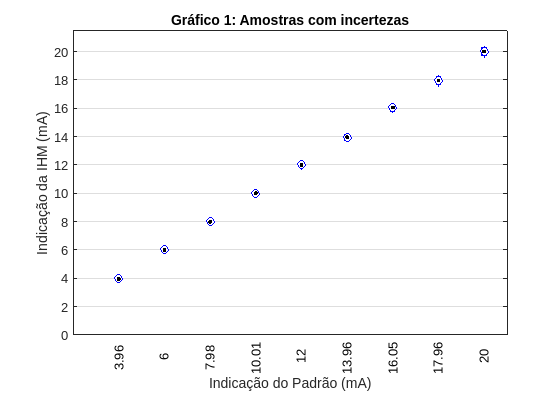

figure('Name', 'Gráfico 1: Amostras com incertezas');
title('Gráfico 1: Amostras com incertezas');
hold on;
boxplot(X, 'PlotStyle', 'compact', 'Labels', padrao_ma)
xlabel('Indicação do Padrão (mA)');
ylabel('Indicação da IHM (mA)');
grid on;
hold off;

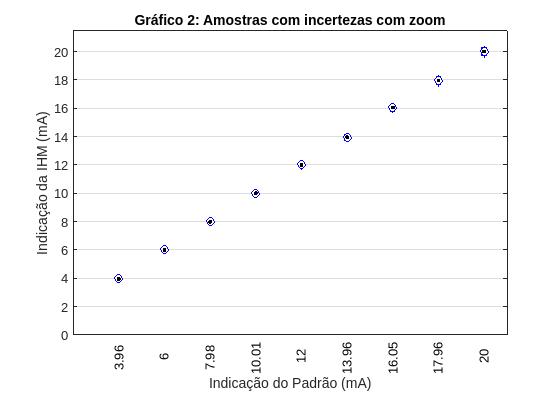


% Gráfico Medições + Barra de Incertezas com ZOOM em alguns pontos
figure('Name', 'Gráfico 2: Amostras com incertezas com zoom');
title('Gráfico 2: Amostras com incertezas com zoom');
hold on;
boxplot(X, 'PlotStyle', 'compact', 'Labels', padrao_ma)
xlabel('Indicação do Padrão (mA)');
ylabel('Indicação da IHM (mA)');
grid on;
hold off;

14) Estime uma reta de calibração para o experimento (Indicações IHM x Indicações Amperímetro), utilizando o algoritmo de Mínimos Quadrados. Apresente a equação da reta de calibração e os valores da sensibilidade e do erro sistemático.

% Estimação da Reta de Calibração por MQ
theta = [ones(length(padrao_ma), 1), padrao_ma'] \ ihm_ma'

theta =     0.0340
    0.9951


fprintf('y = sensibilidade * x + (erro sistematico) = %.2fx + %.2f', theta(2), theta(1))

y = sensibilidade * x + (erro sistematico) = 1.00x + 0.03

y = theta(2) * padrao_ma + theta(1)

y =     3.9747    6.0047    7.9751    9.9952   11.9755   13.9260   16.0058   17.9065   19.9365


14.1) Plote a reta de calibração estimada sobreposto aos pontos $x_{1,\;2,\;\ldotp \ldotp \ldotp } \pm U_{1,\;2,\;\ldotp \ldotp \ldotp }$ configurardos no item anterior. 

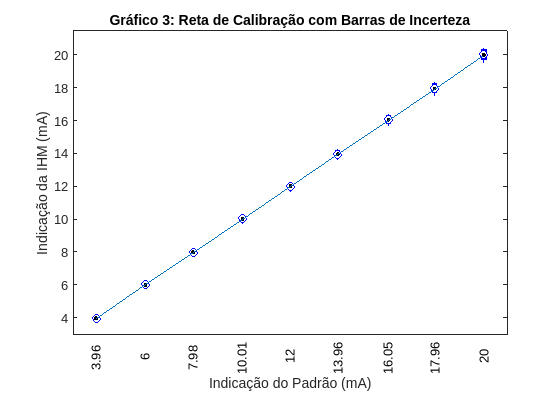

% Gráfico da Reta de Calibração + Medições + Barras de Incertezas
boxplot(X, 'Positions', padrao_ma, 'PlotStyle', 'compact', 'Labels', padrao_ma)
title('Gráfico 3: Reta de Calibração com Barras de Incerteza');
hold on
plot(padrao_ma, y)
xlabel('Indicação do Padrão (mA)');
ylabel('Indicação da IHM (mA)');
hold off

clf

14.2)** Verifique e comente**, de forma quantitativa, se as indicações mostradas pela IHM (Intouch) estão adequadas, tendo como referência a incerteza do amperímetro utilizado ($x_{1,\;2,\;\ldotp \ldotp \ldotp } \pm U_{1,\;2,\;\ldotp \ldotp \ldotp }$). 

        As indicações estão adequadas, já que a reta que melhor as estima é admitida pelas incertezas do padrão.

## Aula Prática 04

Após realizar os Procedimentos Experimentais de 1 a 10 da Aula Prática 04, resolva os procedimentos a seguir:

**Preparação para os Procedimentos 11 a 18:**

Registre, em ordem crescente, os pontos de pressão e de corrente indicados pelo Padrão de Medição utilizado e pela Interface SCADA (IHM).

% Padrão (kPa): [ <valores> ]
% IHM (kPa): [ <valores> ]
% Padrão (mA): [ <valores> ]
% IHM (mA): [ <valores> ]

padrao_kpa = [0.0, 5.0, 10.06, 15.04, 20.03, 25.04, 30.0, 35.0, 40.01, 45.0, 50.01]';
ihm_kpa = [0.0, 5.14, 10.3, 15.36, 20.35, 25.36, 30.35, 35.25, 40.2, 45.05, 49.95]';
padrao_ma = [4.012, 5.657, 7.311, 8.936, 10.54, 12.147, 13.733, 15.317, 16.893, 18.466, 20.006]';
ihm_ma = [4.0, 5.65, 7.293, 8.92, 10.52, 12.12, 13.71, 15.29, 16.85, 18.44, 19.96]';



11) Utilizando o algoritmo de Mínimos Quadrados e com os pontos coletados, realize o ajuste da **reta de calibração** (Indicações do Padrão x Indicações da IHM) para o experimento de calibração realizado com o sistema de medição. 

% Estimação da Reta de Calibração por MQ
theta = [ones(length(padrao_kpa), 1), padrao_kpa] \ ihm_kpa

theta =     0.2345
    0.9983


fprintf('y = %.2fx + %.2f', theta(2), theta(1))

y = 1.00x + 0.23

11.1) Plote a reta de calibração estimada. O gráfico da reta de calibração deve estar sobreposto ao pontos coletados (marcados com um círculo - "o"). **Não se esqueça de mostrar a equação da reta.**

% Gráfico da Reta de Calibração
y = theta(2) * padrao_kpa + theta(1)

y =     0.2345
    5.2261
   10.2777
   15.2494
   20.2311
   25.2327
   30.1844
   35.1761
   40.1777
   45.1594


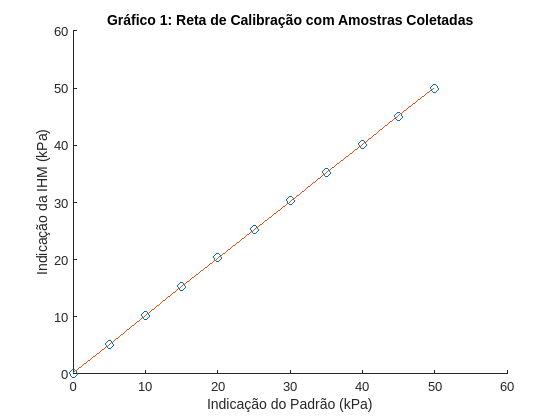

scatter(padrao_kpa, ihm_kpa)
xlabel('Indicação do Padrão (kPa)');
ylabel('Indicação da IHM (kPa)');
hold on
title('Gráfico 1: Reta de Calibração com Amostras Coletadas');
plot(padrao_kpa, y)
hold off

12) Baseando-se nos dados do experimento, calcule e expresse o erro sistemático desse sistema de medição, bem como a sua sensibilidade.

% Erro sistemático e sensibilidade
fprintf('Sensibilidade: %.2f', theta(2));

Sensibilidade: 1.00

fprintf('Erro sistemático: %.2f', theta(1));

Erro sistemático: 0.23

13) Levando em consideração a combinação das incertezas. 

13.1) Qual a **incerteza padrão **considerando o erro de estimação dos parâmetros ***a*** e ***b*** da reta de calibração?

% Incerteza padrão do tipo A
res = ihm_kpa - y;
n = length(padrao_kpa);
incerteza_reg = sqrt(sum(res.^2) / (n - 2));
sxx = sum((padrao_kpa - mean(padrao_kpa)).^2);
incerteza_b = sqrt(incerteza_reg^2 / sxx);
incerteza_a = sqrt(incerteza_reg^2 * (1/n + mean(padrao_kpa)^2 / sxx));
fprintf('Incertezas:\n');

Incertezas:


fprintf('\tRegressão: %.2f', incerteza_reg);

	Regressão: 0.15

fprintf('\tSensibilidade: %.2f', incerteza_a);

	Sensibilidade: 0.08

fprintf('\tErro Sistemático: %.2f', incerteza_b);

	Erro Sistemático: 0.00

13.2) Qual a **incerteza padrão** do manômetro padrão do calibrador Fluke 718 em kPa? **ATENÇÃO:** assuma um intervalo de confiança de 95%.

    Segundo (2), para o instrumento usado:

    - Faixa de medição: -83 a 207 kPa;

    - Faixa Total (Span): 207 kPa - (-83 kPa) = 290 kPa;

    - Incerteza Expandida (U): 0.05% × 290 kPa = 0.0005×290 = 0.145 kPa;

    - Incerteza Padrão (u): 20.145 kPa �= 0.0725 kPa.

2: FLUKE. Fluke 718 User Manual, 1998.

    13.3) Qual a **incerteza padrão** do cartão analógico do CLP em kPa? **ATENÇÃO:** assuma um intervalo de confiança de 95%.

Segundo (3), para o instrumento usado:

    - Exatidão: 0.2% da escala cheia;

    - Incerteza Expandida (U) em mA: 0.2% × 20 mA = 0.04 mA;

    - Incerteza Expandida (U) em kPa: 0.04 mA × (50 kPa / 16 mA) = 0.125 kPa;

    - Incerteza Padrão (u): 0.125 kPa / 2 = 0.0625 kPa.

3: ROCKWELL AUTOMATION. Compact Combination Fast Analog I/O Module - 1769-IF4FXOF2F, 2007.

13.4) Considerando as incertezas calculadas anteriormente, calcule a incerteza expandida da** indicação** do instrumento, para um intervalo de confiança de 95% (para $v\longrightarrow \infty ,t\longrightarrow 1,960$).

- **DICA:** siga o Roteiro 1 (disponível no moodle). Entenda que é necessário calcular a incerteza padrão combinada e um vetor de graus de liberdade efetivo, bem como outro vetor de coeficientes t-Student.

% Incertezas Padrão (Tipo A e B)
% Incerteza do Padrão (Fluke 718 30G)
u_padrao = 0.0725; % (kPa)
% Incerteza do Cartão Analógico (Rockwell)
u_cartao = 0.0625; % (kPa)

% Incerteza da Reta de Calibração (Tipo A).
u_A_sq = incerteza_reg^2 * (1/n + (padrao_kpa - mean(padrao_kpa)).^2 / sxx);
u_A = sqrt(u_A_sq);

% Incerteza Padrão Combinada (u_c)
u_c_sq = u_A_sq + u_padrao^2 + u_cartao^2;
u_c = sqrt(u_c_sq);

fprintf('Vetor de Incerteza Padrão Combinada (u_c) [kPa]:\n');

Vetor de Incerteza Padrão Combinada (u_c) [kPa]:


disp(u_c');

    0.1268    0.1196    0.1136    0.1092    0.1065    0.1055    0.1065    0.1092    0.1136    0.1195    0.1268




% Graus de Liberdade Efetivos
nu_A = n - 2; 
% ν para Tipo B é considerado infinito.
nu_eff = (u_c.^4) ./ (u_A.^4 / nu_A);

fprintf('Vetor de Graus de Liberdade Efetivos (nu_eff):\n');

Vetor de Graus de Liberdade Efetivos (nu_eff):


disp(nu_eff');

   48.6318   69.7081  107.0865  167.9643  245.4795  286.5929  245.5450  167.8839  106.7465   69.8984   48.7096




% Fator de Abrangência (t-Student) e Incerteza Expandida (U)
k = tinv(0.975, nu_eff); 

% A Incerteza Expandida é U = k * u_c
U = k .* u_c;

fprintf('Vetor de Incerteza Expandida (U) [kPa] para 95%% de confiança:\n');

Vetor de Incerteza Expandida (U) [kPa] para 95% de confiança:


disp(U');

    0.2549    0.2385    0.2252    0.2156    0.2097    0.2077    0.2097    0.2156    0.2253    0.2384    0.2548



14) Baseando-se no vetor de incertezas expandidas calculado, indique e justifique qual é o melhor erro a ser expresso: máximo, mínimo, médio ou mediano?

        Ao declarar uma única incerteza para um instrumento, a prática recomendada é usar o valor de pior caso. Portanto, a escolha da incerteza máxima é correta.

14.1) Expresse esse **erro** em sua forma **fiducial** ao sistema de medição (em % do F.E.).

% Erro fiducial 
U_max = max(U);
fundo_escala_kpa = 50;
erro_fiducial_percent = (U_max / fundo_escala_kpa) * 100;
fprintf('A incerteza expandida máxima é: %.4f kPa\n', U_max);

A incerteza expandida máxima é: 0.2549 kPa


fprintf('O erro fiducial é: %.4f %% do F.E.\n', erro_fiducial_percent);

O erro fiducial é: 0.5098 % do F.E.


15) Após a calibração desse sistema de medição, diante o erro apresentado no item anterior, expresse o **resultado de medição** para as indicações (**não-corrigidas**) referentes às medidas 1, 4, 7 e 9. **Comente os resultados obtidos**.

% Expressão das Medidas 1, 4, 7 e 9
% Índices das medidas a serem analisadas
indices = [1, 4, 7, 9];

% Selecionar os dados para essas medidas
ihm_selecionado = ihm_kpa(indices);
U_selecionado = U(indices);
padrao_original = padrao_kpa(indices); % Para comparação

% Coeficientes da reta de calibração
a = theta(1); % Intercepto
b = theta(2); % Inclinação

% Calcular os valores corrigidos
kpa_corrigido = (ihm_selecionado - a) / b;

% Exibir os resultados
fprintf('Expressão dos resultados de medição para 95%% de confiança:\n\n');

Expressão dos resultados de medição para 95% de confiança:




for i = 1:length(indices)
    fprintf('Medida %d:\n', indices(i));
    fprintf('  - Leitura Original IHM: %.2f kPa\n', ihm_selecionado(i));
    fprintf('  - Valor Corrigido: %.2f kPa\n', kpa_corrigido(i));
    fprintf('  - Incerteza Expandida: %.2f kPa\n', U_selecionado(i));
    fprintf('  - Resultado Final: (%.2f ± %.2f) kPa\n', kpa_corrigido(i), U_selecionado(i));
    fprintf('  - (Valor do Padrão original para comparação era: %.2f kPa)\n\n', padrao_original(i));
end

Medida 1:


  - Leitura Original IHM: 0.00 kPa


  - Valor Corrigido: -0.23 kPa


  - Incerteza Expandida: 0.25 kPa


  - Resultado Final: (-0.23 ± 0.25) kPa


  - (Valor do Padrão original para comparação era: 0.00 kPa)



Medida 4:


  - Leitura Original IHM: 15.36 kPa


  - Valor Corrigido: 15.15 kPa


  - Incerteza Expandida: 0.22 kPa


  - Resultado Final: (15.15 ± 0.22) kPa


  - (Valor do Padrão original para comparação era: 15.04 kPa)



Medida 7:


  - Leitura Original IHM: 30.35 kPa


  - Valor Corrigido: 30.17 kPa


  - Incerteza Expandida: 0.21 kPa


  - Resultado Final: (30.17 ± 0.21) kPa


  - (Valor do Padrão original para comparação era: 30.00 kPa)



Medida 9:


  - Leitura Original IHM: 40.20 kPa


  - Valor Corrigido: 40.03 kPa


  - Incerteza Expandida: 0.23 kPa


  - Resultado Final: (40.03 ± 0.23) kPa


  - (Valor do Padrão original para comparação era: 40.01 kPa)



16) Plote novamente a reta de calibração sobreposta aos pontos coletados, acrescida da **região 01** de incertezas **sem o fator de expansão**,* i.e*., apenas a incerteza padrão combinada, bem como acrescida da **região 02** de incertezas **com o fator de expansão**,* i.e*., o *t-student *encontrado para 95% (região do intervalo de confiança calculado). 

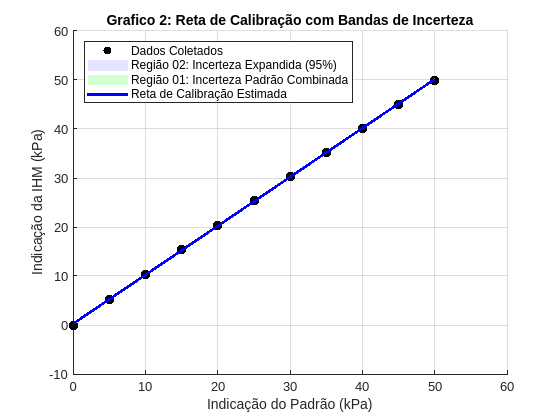

% Gráfico da Reta de Calibração + Medições + Região 01 + Região 02
% Gráfico dos pontos coletados
scatter(padrao_kpa, ihm_kpa, 50, 'k', 'filled', 'DisplayName', 'Dados Coletados');
hold on;

% Coordenadas para preenchimento das áreas de incerteza
x_fill = [padrao_kpa', fliplr(padrao_kpa')]; % Cria um polígono no eixo x

% Limites da Região 02 (Incerteza Expandida, U)
y_lim_inf_U = (y - U)';
y_lim_sup_U = (y + U)';
y_fill_U = [y_lim_inf_U, fliplr(y_lim_sup_U)];
fill(x_fill, y_fill_U, [0.8 0.8 1], 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'DisplayName', 'Região 02: Incerteza Expandida (95%)');

% Limites da Região 01 (Incerteza Padrão Combinada, u_c)
y_lim_inf_uc = (y - u_c)';
y_lim_sup_uc = (y + u_c)';
y_fill_uc = [y_lim_inf_uc, fliplr(y_lim_sup_uc)];
fill(x_fill, y_fill_uc, [0.7 1 0.7], 'FaceAlpha', 0.6, 'EdgeColor', 'none', 'DisplayName', 'Região 01: Incerteza Padrão Combinada');

% Gráfico da reta de calibração sobre as áreas
plot(padrao_kpa, y, 'b-', 'LineWidth', 2, 'DisplayName', 'Reta de Calibração Estimada');

% Configurações do gráfico
title('Grafico 2: Reta de Calibração com Bandas de Incerteza');
xlabel('Indicação do Padrão (kPa)');
ylabel('Indicação da IHM (kPa)');
legend('Location', 'northwest');
grid on;
hold off;

16.1) Você observa algum ponto coletado fora da **região 01**? E fora da **região 02**? **Comente os resultados obtidos**. 

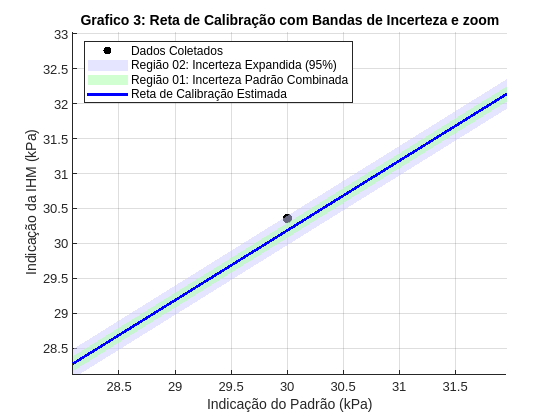

% Gráfico anterior com ZOOM em alguns pontos
scatter(padrao_kpa, ihm_kpa, 50, 'k', 'filled', 'DisplayName', 'Dados Coletados');
hold on;

% Coordenadas para preenchimento das áreas de incerteza
x_fill = [padrao_kpa', fliplr(padrao_kpa')]; % Cria um polígono no eixo x

% Limites da Região 02 (Incerteza Expandida, U)
y_lim_inf_U = (y - U)';
y_lim_sup_U = (y + U)';
y_fill_U = [y_lim_inf_U, fliplr(y_lim_sup_U)];
fill(x_fill, y_fill_U, [0.8 0.8 1], 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'DisplayName', 'Região 02: Incerteza Expandida (95%)');

% Limites da Região 01 (Incerteza Padrão Combinada, u_c)
y_lim_inf_uc = (y - u_c)';
y_lim_sup_uc = (y + u_c)';
y_fill_uc = [y_lim_inf_uc, fliplr(y_lim_sup_uc)];
fill(x_fill, y_fill_uc, [0.7 1 0.7], 'FaceAlpha', 0.6, 'EdgeColor', 'none', 'DisplayName', 'Região 01: Incerteza Padrão Combinada');

% Gráfico da reta de calibração sobre as áreas
plot(padrao_kpa, y, 'b-', 'LineWidth', 2, 'DisplayName', 'Reta de Calibração Estimada');

% Configurações do gráfico
title('Grafico 3: Reta de Calibração com Bandas de Incerteza e zoom');
xlabel('Indicação do Padrão (kPa)');
ylabel('Indicação da IHM (kPa)');
legend('Location', 'northwest');
grid on;
hold off;

xlim([28.09 31.96])
ylim([28.13 33.04])

17) Calcule a *linearidade *do sistema de medição, para o experimento de calibração realizado. **Comente os resultados obtidos.**

% Linearidade
% 2. Encontrar o desvio máximo absoluto
res_maximo = max(abs(res));

% 3. Calcular o span (faixa total de medição) da saída (IHM)
span_saida = max(ihm_kpa) - min(ihm_kpa);

% 4. Calcular o erro de linearidade em porcentagem
erro_linearidade_percent = (res_maximo / span_saida) * 100;

fprintf('\n--- Resultados do Procedimento 17 ---\n');


--- Resultados do Procedimento 17 ---


fprintf('O desvio máximo da reta de calibração foi: %.4f kPa\n', res_maximo);

O desvio máximo da reta de calibração foi: 0.2345 kPa


fprintf('O span de saída (IHM) foi: %.4f kPa\n', span_saida);

O span de saída (IHM) foi: 49.9500 kPa


fprintf('O erro de linearidade do sistema é: %.4f %% do Span\n', erro_linearidade_percent);

O erro de linearidade do sistema é: 0.4694 % do Span


    O erro de linearidade de **0.2839%** indica o quão bem a resposta do sistema de medição se conforma a um modelo linear. Um valor baixo como este é geralmente considerado bom, sugerindo que o sistema se comporta de maneira previsível e consistente em toda a sua faixa de operação. Isso significa que o uso de uma reta para corrigir as medições é uma abordagem válida e eficaz, pois os desvios não-lineares são pequenos em comparação com a faixa total de medição.

18) Como obter a** indicação corrigida** para esse sistema de medição? A incerteza de medição (intervalos de confiança) podem ser os mesmos obtidos no item 13? **Justifique utilizando cálculos e demonstrações.**

        A indicação corrigida (x) é obtida a partir da leitura do instrumento (y) invertendo a equação da reta de calibração, ou seja, x = (y - a) / b, onde 'a' é o coeficiente linear e 'b' o angular. Contudo, a incerteza de medição não é a mesma para todos os pontos da faixa e deve ser recalculada para cada valor. A justificativa está no fato de que a incerteza da calibração depende do próprio valor medido, como mostra a fórmula da sua componente principal: u_A^2 = s_yx^2 * (1/n + (x - x_medio)^2 / Sxx). O termo (x - x_medio)^2 demonstra que a incerteza é mínima no centro da faixa e aumenta em direção às extremidades, o que foi comprovado pelo vetor de incertezas calculado e pelo gráfico com as bandas em formato de "gravata-borboleta".

## Aula Prática 05

Após realizar os Procedimentos Experimentais de 1 a 10 da Aula Prática 05, resolva os procedimentos a seguir:

**Preparação para os Procedimentos 11 a 19:**

Registre, em ordem crescente, os pontos de pressão e de corrente indicados pelo Padrão de Medição utilizado e pela Interface SCADA (IHM).

% Dados Coletados
% % Padrão (°C): Valores lidos no instrumento padrão (Fluke)
padrao_c = [0.1, 0.2, 24.9, 30.5, 41.9, 51.5, 60.6, 69.9, 79.7];

% % IHM (°C): Valores de temperatura lidos na Interface Homem-Máquina
ihm_c = [0.07, 0.05, 24.85, 30.05, 42.45, 51.16, 60.81, 70.15, 80.23];

% % IHM (mA): Valores de corrente correspondentes lidos na IHM
ihm_ma = [4.062, 3.995, 8.926, 10.032, 12.494, 14.229, 16.149, 17.99, 20.04];

%% Parâmetros do Experimento
n = length(padrao_c); % Número de pontos coletados
FULL_SCALE = 100.0;   % Fundo de Escala (F.E.)

11) Utilizando o algoritmo de Mínimos Quadrados e com os pontos coletados, realize o ajuste da **reta de calibração** (Indicações do Padrão x Indicações da IHM) para o experimento de calibração realizado com o sistema de medição. 

p = polyfit(padrao_c, ihm_c, 1);
a = p(1);
b = p(2);

% Calcula os valores de y na reta estimada para cada ponto de x
y_estimado = polyval(p, padrao_c);

% Exibe a equação da reta no Command Window
fprintf('A equação da reta de calibração é: y = %.2fx + %.2f\n\n', a, b);

A equação da reta de calibração é: y = 1.01x + -0.20



11.1) Plote a reta de calibração estimada. O gráfico da reta de calibração deve estar sobreposto ao pontos coletados (marcados com um círculo - "o"). **Não se esqueça de mostrar a equação da reta.**

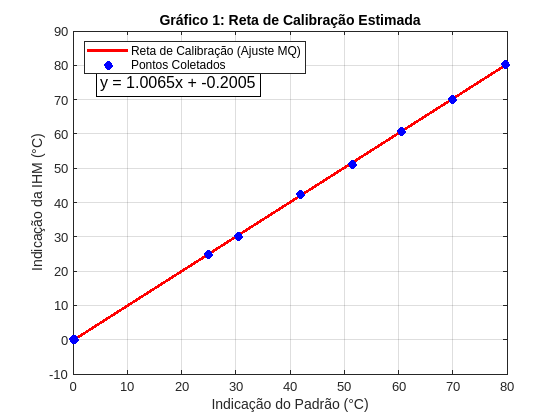

% Gráfico da Reta de Calibração
figure('Name', 'Gráfico 1: Reta de Calibração');
plot(padrao_c, y_estimado, '-r', 'LineWidth', 2, 'DisplayName', 'Reta de Calibração (Ajuste MQ)');
hold on;
plot(padrao_c, ihm_c, 'ob', 'MarkerFaceColor', 'b', 'DisplayName', 'Pontos Coletados');
hold off;

title('Gráfico 1: Reta de Calibração Estimada');
xlabel('Indicação do Padrão (°C)');
ylabel('Indicação da IHM (°C)');
legend('show', 'Location', 'northwest');
grid on;

% Adiciona a equação da reta no gráfico
equation_text = sprintf('y = %.4fx + %.4f', a, b);
text(5, 75, equation_text, 'FontSize', 12, 'BackgroundColor', 'white', 'EdgeColor', 'black');

12) Baseando-se nos dados do experimento, calcule e expresse o erro sistemático desse sistema de medição, bem como a sua sensibilidade.

% Erro sistemático e sensibilidade
sensibilidade = a;
erro_sistematico = b;

fprintf('--- 12) Erro Sistemático e Sensibilidade ---\n');

--- 12) Erro Sistemático e Sensibilidade ---


fprintf('Sensibilidade (coeficiente angular ''a''): %.6f (°C IHM / °C Padrão)\n', sensibilidade);

Sensibilidade (coeficiente angular 'a'): 1.006470 (°C IHM / °C Padrão)


fprintf('Erro Sistemático (offset ''b''): %.6f °C\n\n', erro_sistematico);

Erro Sistemático (offset 'b'): -0.200522 °C



13) Levando em consideração a combinação das incertezas. 

13.1) Qual a **incerteza padrão** considerando o erro de estimação dos parâmetros ***a*** e ***b*** da reta de calibração?

% Incerteza padrão do tipo A
residuos = ihm_c - y_estimado;
s_yx = sqrt(sum(residuos.^2) / (n - 2)); % Desvio padrão dos resíduos
S_xx = sum((padrao_c - mean(padrao_c)).^2);
u_A = s_yx .* sqrt(1/n + (padrao_c - mean(padrao_c)).^2 / S_xx);
fprintf('Incerteza Padrão Tipo A (u_A) para cada ponto:\n');

Incerteza Padrão Tipo A (u_A) para cada ponto:


disp(u_A);

    0.1923    0.1920    0.1233    0.1141    0.1080    0.1172    0.1358    0.1612    0.1921



13.2) Qual a **incerteza padrão** do termômetro padrão Fluke 51/52 II em °C? **ATENÇÃO:** assuma um intervalo de confiança de 95%.

% Incerteza padrão do tipo B (padrão de medição)
k_normal = 1.96;
incerteza_fluke = 0.0005 * padrao_c + 0.3;
u_B_padrao = incerteza_fluke / k_normal;
fprintf('Incerteza Padrão Tipo B do Padrão Fluke (u_B_padrao):\n');

Incerteza Padrão Tipo B do Padrão Fluke (u_B_padrao):


disp(u_B_padrao);

    0.1531    0.1531    0.1594    0.1608    0.1638    0.1662    0.1685    0.1709    0.1734



13.3) Qual a incerteza do cartão analógico do CLP em °C? **ATENÇÃO:** assuma um intervalo de confiança de 95%.

% Incerteza paddrão do tipo B (cartão do CLP)
k_retangular = sqrt(3);
incerteza_clp = 0.0015 * FULL_SCALE;
u_B_clp = incerteza_clp / k_retangular;
fprintf('Incerteza Padrão Tipo B do Cartão CLP (u_B_clp): %.6f °C (constante)\n\n', u_B_clp);

Incerteza Padrão Tipo B do Cartão CLP (u_B_clp): 0.086603 °C (constante)



13.4) Considerando as incertezas calculadas anteriormente, calcule a incerteza expandida da indicação do instrumento, para um intervalo de confiança de 95% (para $v\longrightarrow \infty ,t\longrightarrow 1,960$).

- **DICA:** siga o Roteiro 1 (disponível no moodle). Entenda que é necessário calcular a incerteza padrão combinada e um vetor de graus de liberdade efetivo, bem como outro vetor de coeficientes t-Student.

% Incerteza Combinada
u_c = sqrt(u_A.^2 + u_B_padrao.^2 + u_B_clp^2);
fprintf('Incerteza Padrão Combinada (u_c):\n');

Incerteza Padrão Combinada (u_c):


disp(u_c);

    0.2606    0.2604    0.2194    0.2154    0.2144    0.2211    0.2331    0.2504    0.2729




v_A = n - 2;
v_eff = u_c.^4 ./ (u_A.^4 / v_A);
fprintf('Graus de Liberdade Efetivos (v_eff):\n');

Graus de Liberdade Efetivos (v_eff):


disp(v_eff);

   23.6128   23.6926   70.0618   88.8544  108.7828   88.4762   60.7761   40.7501   28.4919




k_t_student = tinv(0.975, v_eff);
fprintf('Fator de Abrangência t-Student (k):\n');

Fator de Abrangência t-Student (k):


disp(k_t_student);

    2.0657    2.0653    1.9944    1.9870    1.9820    1.9871    1.9998    2.0199    2.0468




% Incerteza Expandida
U = k_t_student .* u_c;
fprintf('Incerteza Expandida para 95%% de confiança (U):\n');

Incerteza Expandida para 95% de confiança (U):


disp(U);

    0.5383    0.5377    0.4375    0.4280    0.4250    0.4393    0.4662    0.5057    0.5586



14) Baseando-se no vetor de incertezas expandidas calculado, expresse o **erro** em sua forma **fiducial** ao sistema de medição (em % do F.E.).

% Erro fiducial 
% Erro fiducial = (Incerteza Expandida / Fundo de Escala) * 100
erro_fiducial_percent = (U / FULL_SCALE) * 100;

fprintf('O erro em sua forma fiducial é (%% F.E.):\n');

O erro em sua forma fiducial é (% F.E.):


disp(erro_fiducial_percent);

    0.5383    0.5377    0.4375    0.4280    0.4250    0.4393    0.4662    0.5057    0.5586



15) Após a calibração desse sistema de medição, diante o erro apresentado no item anterior, expresse o **resultado de medição** para as indicações (**não-corrigidas**) referentes às medidas 1, 3, 5 e 8. **Comente os resultados obtidos**.

% Expressão das Medidas 1, 3, 5 e 8
indices_medidas = [1, 3, 5, 8]; 

for i = 1:length(indices_medidas)
    idx = indices_medidas(i);
    fprintf('Medida %d: (%.2f ± %.2f) °C\n', idx, ihm_c(idx), U(idx));
end

Medida 1: (0.07 ± 0.54) °C
Medida 3: (24.85 ± 0.44) °C
Medida 5: (42.45 ± 0.42) °C
Medida 8: (70.15 ± 0.51) °C


16) Plote novamente a reta de calibração sobreposta aos pontos coletados, acrescida da **região 01** de incertezas **sem o fator de expansão**,* i.e*., apenas a incerteza padrão combinada, bem como acrescida da **região 02** de incertezas **com o fator de expansão**,* i.e*., o *t-student *encontrado para 95% (região do intervalo de confiança calculado).

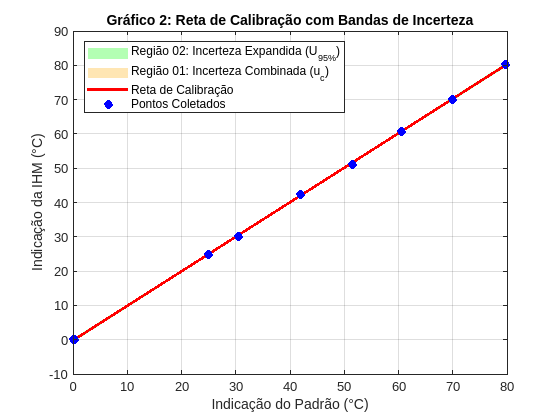

% Gráfico da Reta de Calibração + Medições + Região 01 + Região 02
figure('Name', 'Gráfico 2: Calibração com Bandas de Incerteza');

x_fill = [padrao_c, fliplr(padrao_c)];

% Região 02: Incerteza Expandida (U) - plotada primeiro para ficar no fundo
y_fill_U = [y_estimado - U, fliplr(y_estimado + U)];
fill(x_fill, y_fill_U, [0.7 1 0.7], 'EdgeColor', 'none', 'DisplayName', 'Região 02: Incerteza Expandida (U_{95%})');
hold on;

% Região 01: Incerteza Padrão Combinada (u_c)
y_fill_uc = [y_estimado - u_c, fliplr(y_estimado + u_c)];
fill(x_fill, y_fill_uc, [1 0.9 0.7], 'EdgeColor', 'none', 'DisplayName', 'Região 01: Incerteza Combinada (u_c)');

% Reta e pontos (plotados por último para ficarem na frente)
plot(padrao_c, y_estimado, '-r', 'LineWidth', 2, 'DisplayName', 'Reta de Calibração');
plot(padrao_c, ihm_c, 'ob', 'MarkerFaceColor', 'b', 'DisplayName', 'Pontos Coletados');

title('Gráfico 2: Reta de Calibração com Bandas de Incerteza');
xlabel('Indicação do Padrão (°C)');
ylabel('Indicação da IHM (°C)');
legend('show', 'Location', 'northwest');
grid on;
hold off;

16.1) Você observa algum ponto coletado fora da** região 01**? E fora da **região 02**? **Comente os resultados obtidos.**

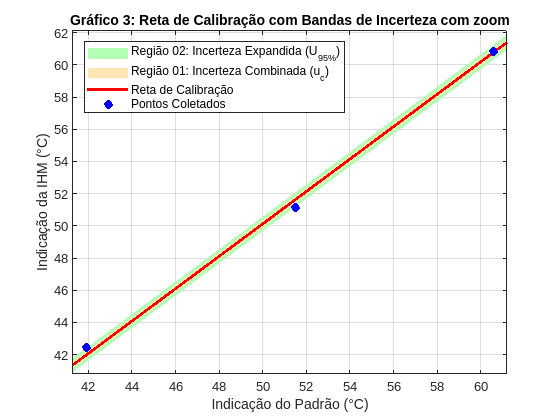

% Gráfico anterior com ZOOM em alguns pontos
figure('Name', 'Gráfico 2: Calibração com Bandas de Incerteza');

x_fill = [padrao_c, fliplr(padrao_c)];

% Região 02: Incerteza Expandida (U) - plotada primeiro para ficar no fundo
y_fill_U = [y_estimado - U, fliplr(y_estimado + U)];
fill(x_fill, y_fill_U, [0.7 1 0.7], 'EdgeColor', 'none', 'DisplayName', 'Região 02: Incerteza Expandida (U_{95%})');
hold on;

% Região 01: Incerteza Padrão Combinada (u_c)
y_fill_uc = [y_estimado - u_c, fliplr(y_estimado + u_c)];
fill(x_fill, y_fill_uc, [1 0.9 0.7], 'EdgeColor', 'none', 'DisplayName', 'Região 01: Incerteza Combinada (u_c)');

% Reta e pontos (plotados por último para ficarem na frente)
plot(padrao_c, y_estimado, '-r', 'LineWidth', 2, 'DisplayName', 'Reta de Calibração');
plot(padrao_c, ihm_c, 'ob', 'MarkerFaceColor', 'b', 'DisplayName', 'Pontos Coletados');

title('Gráfico 3: Reta de Calibração com Bandas de Incerteza com zoom');
xlabel('Indicação do Padrão (°C)');
ylabel('Indicação da IHM (°C)');
legend('show', 'Location', 'northwest');
grid on;
hold off;

xlim([41.3 61.2])
ylim([40.8 62.1])

17) Calcule a *linearidade *do sistema de medição para o experimento de calibração realizado. **Comente os resultados obtidos.**

% Linearidade
desvios = ihm_c - y_estimado; % mesmos que os resíduos
linearidade_abs = max(abs(desvios));
linearidade_percent = (linearidade_abs / FULL_SCALE) * 100;

fprintf('O desvio máximo da reta de calibração foi de: %.4f °C\n', linearidade_abs);

O desvio máximo da reta de calibração foi de: 0.4794 °C


fprintf('A linearidade, expressa em %% do Fundo de Escala (%.1f°C), é: %.4f %%\n', FULL_SCALE, linearidade_percent);

A linearidade, expressa em % do Fundo de Escala (100.0°C), é: 0.4794 %


18) A incerteza do sistema de medição seria afetada caso o sensor utilizado fosse um Pt2000? Por quê? **Discuta demonstrando com cálculos.**

        A substituição do sensor de termopar por um Pt2000 afetaria diretamente a incerteza total do sistema de medição, pois cada componente da cadeia de medição adiciona sua própria incerteza ao resultado final. Um sensor Pt2000 possui especificações de precisão próprias, como a Classe B da norma IEC 60751, que introduziriam uma nova fonte de incerteza quantificável no cálculo. Essa nova incerteza do sensor precisaria ser somada às outras fontes (do ajuste da reta, do padrão e do cartão CLP), resultando em um aumento do valor final da incerteza combinada e, consequentemente, da incerteza expandida do sistema.

## Aula Prática 06

Após realizar os Procedimentos Experimentais de 1 a 7 da Aula Prática 06, resolva os procedimentos a seguir:

**Preparação para os Procedimentos 8 a 17:**

Registre, em ordem crescente, os pontos de pressão e de corrente indicados pelo Padrão de Medição utilizado e pela Interface SCADA (IHM).

% Padrão (g): [ <valores> ]
% IHM (g): [ <valores> ]
% IHM (mA): [ <valores> ]

8) Utilizando o algoritmo de Mínimos Quadrados e com os pontos coletados, realize o ajuste da **reta de calibração** (Indicações do Padrão x Indicações da IHM) para o experimento de calibração realizado com o sistema de medição.

% Estimação da Reta de Calibração por MQ


8.1) Plote a reta de calibração estimada. O gráfico da reta de calibração deve estar sobreposto ao pontos coletados (marcados com um círculo - "o"). **Não se esqueça de mostrar a equação da reta.**

% Gráfico da Reta de Calibração


9) Baseando-se nos dados do experimento, calcule e expresse o erro sistemático desse sistema de medição, bem como a sua sensibilidade.

% Erro sistemático e sensibilidade


10) Obtenha a **indicação corrigida** para esse sistema de medição.

% Indicação corrigida


10.1) Comparando com as medidas do padrão de medição utilizado, as medidas corrigidas se aproximam melhor deste? **Comente sua resposta.**

        *Resposta em texto...*

11) Levando em consideração a combinação das incertezas. 

11.1) Qual a **incerteza padrão** considerando o erro de estimação dos parâmetros ***a*** e ***b*** da reta de calibração?

% Incerteza padrão do tipo A


11.2) Qual a **incerteza padrão** do Conjunto de Pesos Padrão em g (**assuma o pior caso**)? **ATENÇÃO:** assuma um intervalo de confiança de 95%.

% Incerteza padrão do tipo B (padrão de medição)


11.3) Qual a incerteza do cartão analógico do CLP em g? **ATENÇÃO:** assuma um intervalo de confiança de 95%.

% Incerteza paddrão do tipo B (cartão do CLP)


11.4) Considerando as incertezas calculadas anteriormente, calcule a incerteza expandida da indicação corrigida ($\hat{x}$) do instrumento, para um intervalo de confiança de 95% (para $v\longrightarrow \infty ,t\longrightarrow 1,960$).

- DICA: siga o Roteiro 2 (disponível no moodle). Entenda que é necessário calcular um vetor de graus de liberdade efetivo, bem como outro vetor de coeficientes t-Student.

% Incerteza Combinada

% Incerteza Expandida


12) Baseando-se no vetor de incertezas expandidas calculado, calcule o** erro **em sua forma** fiducial **ao sistema de medição (em % do F.E.)

% Erro fiducial 


13) Após a calibração desse sistema de medição, diante o erro apresentado no item anterior, expresse o **resultado de medição **para as indicações (**corrigidas**) referentes as Medidas 200g, 1.000g, 2.500g e 5.000g. **Comente os resultados obtidos**.

- **OBSERVAÇÃO:** não se esqueça de considerar correção do sistema de medição.

% Expressão das Medidas 200g, 1000g, 2500g e 5000g


14) Plote novamente a reta de calibração sobreposta aos pontos coletados, acrescida da **região 01** de incertezas **sem o fator de expansão**,* i.e*., apenas a incerteza padrão combinada, bem como acrescida da **região 02** de incertezas **com o fator de expansão**,* i.e*., o *t-student *encontrado para 95% (região do intervalo de confiança calculado).

% Gráfico da Reta de Calibração + Medições + Região 01 + Região 02


15) Você observa algum ponto coletado fora da** região 01**? E fora da **região 02**? **Comente os resultados obtidos.**

% Gráfico anterior com ZOOM em alguns pontos


16) Calcule a *linearidade *do sistema de medição, para o experimento de calibração realizado.  

% Linearidade


17) A célula de carga *SP4MAC3/5KG-1* da HBM, utilizada na balança, possui sensibilidade 2 mV/V, *i.e.*, para uma tensão de excitação de 5 V, ela terá um SPAN de 10 mV para a saída, *i.e.*, em 5 kg $\longrightarrow$ 10 mV). Dessa forma, observando o circuito condicionador de sinais da Figura 6.6 do roteiro, calcule a variação de tensão máxima que esta célula de carga fornece para a excitação a qual ela foi submetida.

        *Resposta em texto...*

18) Sob excitação adequada, a menor tensão possível gerada pela célula de carga *SP4MAC3/5KG-1* ocorre para o peso de 1 g. Logo, somente **pesos maiores que 1 g são “detectados”** pela balança. Ainda assim, não é possível realizar medições mesmo maiores que 5 g, por quê? **Discuta sugerindo melhorias nesse sistema de medição.**

        *Resposta em texto...*

## Análise de Resultados 

Compare os procedimentos de calibração realizados nas Aulas Práticas 3, 4, 5 e 6. Quais as principais diferenças entre eles? **ATENÇÃO:** identifique em sua discussão quais procedimentos possuem **padrões de medição variáveis e/ou invariáveis** e avalie **qual o impacto** de um padrão variável/invariável para o experimento de calibração?

        *Resposta em texto...*

Compare as** linearidades **dos sistemas de medição das Aulas Práticas 3, 4, 5 e 6.** Comente. **

        *Resposta em texto...*

Compare os **erros fiduciais** dos sistemas de medição das Aulas Práticas 3, 4, 5 e 6.** Comente.**

        *Resposta em texto...*

O método de cálculo de incertezas utilizado leva em consideração a repetição do experimento de calibração, *i.e.*, $m\ge 1$. Explique o porquê de se utilizar este método? Supondo uma variabilidade normal do experiemento, caso $m\gg 1$ (*i.e.*, $m$ grande), comente o que ocorrerá com o erro de medição?

        *Resposta em texto...*

## Conclusões

Não existe relatório sem conclusão! Seja pragmático e objetivo. Conclua sobre os resultados obtidos, as dificuldades encontradas e as decisões tomadas.

        *Resposta em texto...*